# ROC Curve Analysis

The **receiver operating characteristic (ROC)** curve evaluates how well a continuous or **ordinal** score separates two classes across all possible decision thresholds. This is a well-established framework in statistical learning and machine learning. A major reference is

Fawcett, T. 2006 [An introduction to ROC analysis](https://longliveturtle.github.io/water/p1.pdf). *Pattern recognition letters* 27: 861-874.

© 2026 Moo K. Chung

University of Wisconsin-Madison

In validation settings with known ground truth, performance must be assessed in terms of both false positives and false negatives. Let $y_i \in \{0,1\}, \qquad i=1,\dots,n,$ denote the true label, where $y_i=1$ corresponds to a true signal (positive) and $y_i=0$ corresponds to a null (negative). The resulting decision problem can be viewed as a binary decision rule, or equivalently as a two-sample hypothesis testing problem, where one seeks to distinguish between


$$H_0: y_i = 0 \quad \text{(null)} \qquad \text{and} \qquad H_1: y_i = 1 \quad \text{(signal)}.$$


Let $s_i$ denote the score (test statistic) produced by a method, where** larger values indicate stronger evidence against the null** hypothesis in favor of the alternative. For a given threshold $c$, we define the decision rule


$$\hat{y}_i(c) = \mathbf{1}(s_i \ge c),$$


which corresponds to rejecting $H_0$ whenever the test statistic exceeds $c$. Let $s_i \in \mathbb{R}$ be the score (test statistic) produced by a method, where **larger values indicate stronger evidence for the positive class**. For a given threshold $c$, we classify $\hat{y}_i(c) = \mathbf{1}(s_i \ge c).$

In hypothesis test setting, false positives correspond to Type I errors (incorrectly rejecting $H_0$ when $y_i=0$), while false negatives correspond to Type II errors (failing to reject $H_0$ when $y_i=1$). Varying the threshold $c$ yields a continuum of hypothesis tests with different Type I and Type II error rates. The ROC curve summarizes this trade-off by plotting the true positive rate (power) against the false positive rate (Type I error) across all thresholds, thereby providing a threshold-independent characterization of the discriminative ability of the test statistic.

### True positives and true nagatives

This induces the decomposition into true and false detections:


$$TP(c)=\sum_{i=1}^n \mathbf{1}(y_i=1,\ s_i\ge c).$$


The quantity $TP$ stands for **true positives, ** which counts how many observations are correctly identified as positive. As the threshold decreases, more observations are classified as positive, which implies the monotonic relationships


$$c_1 < c_2 \;\Rightarrow\; TP(c_1) \ge TP(c_2).$$


The quantity $TN$ stands for **true negatives**, which counts how many observations are correctly identified as negative. More precisely,


$$TN(c) = \sum_{i=1}^n \mathbf{1}(y_i = 0,\ s_i < c),$$


which is the number of null cases that are correctly classified as negative by the method. 


$$c_1 < c_2 \;\Rightarrow\; TN(c_1) \le TN(c_2).$$


### False positives and false negatives

$FP$ stands for **false positives**, which counts how many observations are incorrectly identified as positive:


$$FP(c)=\sum_{i=1}^n \mathbf{1}(y_i=0,\ s_i\ge c).$$


Increasing the threshold $c$ makes the classification rule $s_i \ge c$ more restrictive, so fewer observations are labeled as positive. As a result, fewer negative samples $y_i=0$ satisfy this condition, which implies that the number of false positives decreases:


$$c_1 < c_2 \;\Rightarrow\; FP(c_1) \ge FP(c_2).$$


We also have **false negatives **(FN), which counts how many observations are incorrectly identified as negative. 


$$FN(c)=\sum_{i=1}^n \mathbf{1}(y_i=1,\ s_i< c).$$


Since false negatives increase with threshold, we have


$$c_1 < c_2 \;\Rightarrow\; FN(c_1) \le FN(c_2).$$


TP and FN are related through the total number of true positives in the ground truth. Since every true positive case is either correctly detected (TP) or missed (FN), we have

$P = \sum_{i=1}^n \mathbf{1}(y_i = 1) = TP(c) + FN(c)$.

Similarly, the total number of negative (null) observations is either correctly classified as negative or incorrectly classified as positive, and therefore decomposes as


$$N = \sum_{i=1}^n \mathbf{1}(y_i = 0) = N = FP(c) + TN(c).$$


### **True positive rates and false positive rates**

**False positives (FP)**  and **False Negatives (FN)** are inherently coupled through the threshold $c$. Increasing $c$ makes the classifier more conservative, which reduces false positives but increases false negatives. Conversely, decreasing $c$ makes the classifier more permissive, which reduces false negatives but increases false positives. Therefore, a meaningful validation must examine the full trade-off across all values of $c$ rather than relying on a single operating point. To quantify this trade-off, we define

$\mathrm{TPR}(c)=\frac{TP(c)}{TP(c)+FN(c)}= \frac{TP(c)}{P}$. 

Here, $\mathrm{TPR}(c)$ stands for **true positive rate** and measures the ability to avoid false negatives (**sensitivity**) or recall. It is a normalized version of TP. 

$\mathrm{FPR}(c)$ stands for **false postive rate**, which directly measures the rate of false positives:


$$\mathrm{FPR}(c)=\frac{FP(c)}{FP(c)+TN(c)}=\frac{FP(c)}{N}.$$


The true negative rate (**specificity**), is defined as


$$\mathrm{TNR}(c) = \frac{TN(c)}{TN(c) + FP(c)} = 1 - \mathrm{FPR}(c).$$


Simialry, we can define the **false negative rate **as

$\mathrm{FNR}(c)=\frac{FN(c)}{TP(c)+FN(c)} = 1 - \mathrm{TPR}(c)$.

[Self note: Connect to type-I and type-II error. Topological clustering for fixed c. ]. 

### Receiver operating characteristic curve

The receiver operatating chracteristic (ROC) curve is obtained by plotting $\mathrm{TPR}(c)$ against $\mathrm{FPR}(c)$ as $c$ varies over all possible thresholds. Each point on the curve corresponds to a specific balance between false positives and false negatives. A method that minimizes both error types will achieve high $\mathrm{TPR}$ while maintaining low $\mathrm{FPR}$, resulting in a curve that approaches the upper-left corner. In contrast, a method with poor discrimination will exhibit a curve close to the diagonal $\mathrm{TPR}=\mathrm{FPR}$, indicating that reductions in false negatives are achieved only at the cost of proportional increases in false positives.

The area under the ROC curve (AUC) provides a threshold-independent summary of this trade-off:


$$\mathrm{AUC} = \int_0^1 \mathrm{TPR}(u)\, d u,$$


where $u = \mathrm{FPR}(c)$. This provides a geometric interpretation of AUC as the area under the ROC curve in the unit square $[0,1]^2$.

AUC measures how well the method maintains high sensitivity while the tolerance for false positives varies from 0 to 1. A larger AUC indicates that $\mathrm{TPR}(c)$ remains high even when $\mathrm{FPR}(c)$ is kept low, reflecting better separation between positive and negative classes. A method with $\mathrm{AUC} = 1$ achieves $\mathrm{TPR}(c)=1$ for all $u$, corresponding to perfect classification, while $\mathrm{AUC} = 0.5$ corresponds to $\mathrm{TPR}(u)=u$, which is the diagonal line and represents no discriminative ability beyond random chance. This expression shows that AUC measures how often a positive observation receives a higher score than a negative observation, averaged over all such pairs.

For validation studies, ROC analysis is appropriate when the proposed method outputs a ranking score, confidence value, edge weight, statistic, or probability rather than a fixed binary decision. In simulation studies with known ground truth, ROC analysis quantifies how well the method recovers true positives while controlling false discoveries over all thresholds. This is particularly useful when comparing competing methods because it avoids dependence on one arbitrarily chosen cutoff. If the data are imbalanced, ROC curves remain informative, although precision-recall analysis may also be considered when the positive class is very rare.

### Interpretation of ROC curve

In the plot, **sensitivity** measures how good the method is at finding the true signals. A high sensitivity means most of the actual positives are correctly detected, with few missed cases. **Specificity** measures how good the method is at rejecting non-signals. A high specificity means most of the true negatives are correctly identified, with few false alarms. Thus, 1-specificity measures how often the method mistakenly flags a non-signal as a signal, that is, the false positive rate.

An ROC curve can lie below the diagonal line $y=x$, although this indicates worse-than-random performance. The diagonal corresponds to random guessing, where $\mathrm{TPR}(c)=\mathrm{FPR}(c)$. A curve above the diagonal reflects good discrimination, meaning that positive observations tend to receive higher scores than negative ones. In contrast, a curve below the diagonal indicates that the method systematically assigns higher scores to negative observations than to positive ones.

### ROC in graph estimation 

We illustrate ROC analysis in a weighted directed network setting. we first generate a ground-truth directed graph $G$ on $n=10$ nodes with edge connection probability $p_{\mathrm{edge}}=0.3$. The graph is represented by a weighted adjacency matrix


$$C_{\mathrm{truth}} \in \mathbb{R}^{n\times n}.$$


By construction, $C_{\mathrm{truth}}(i,j)\neq 0$ indicates the presence of a directed edge from node $i$ to node $j$, while $C_{\mathrm{truth}}(i,j)=0$ indicates the absence of such an edge. 

clear; clc; close all;

n = 10;
p_edge = 0.2;
G = graph_random_directed(n, p_edge);
C_truth = full(adjacency(G, 'weighted'));

If the noise level  is small, the estimated matrix is close to the ground truth, and hence the AUC is close to 1. As  increases, the estimated matrix becomes increasingly dominated by noise and deviates from the ground truth, and consequently the AUC approaches 0.5, corresponding to random performance.

To mimic estimation error, we perturb the ground-truth weighted adjacency matrix by additive Gaussian noise,


$$\widehat{W} = C_{\mathrm{truth}} + \sigma E,$$


where $\sigma=0.8$ is the noise level and $E$ is a random matrix with independent standard normal entries.  

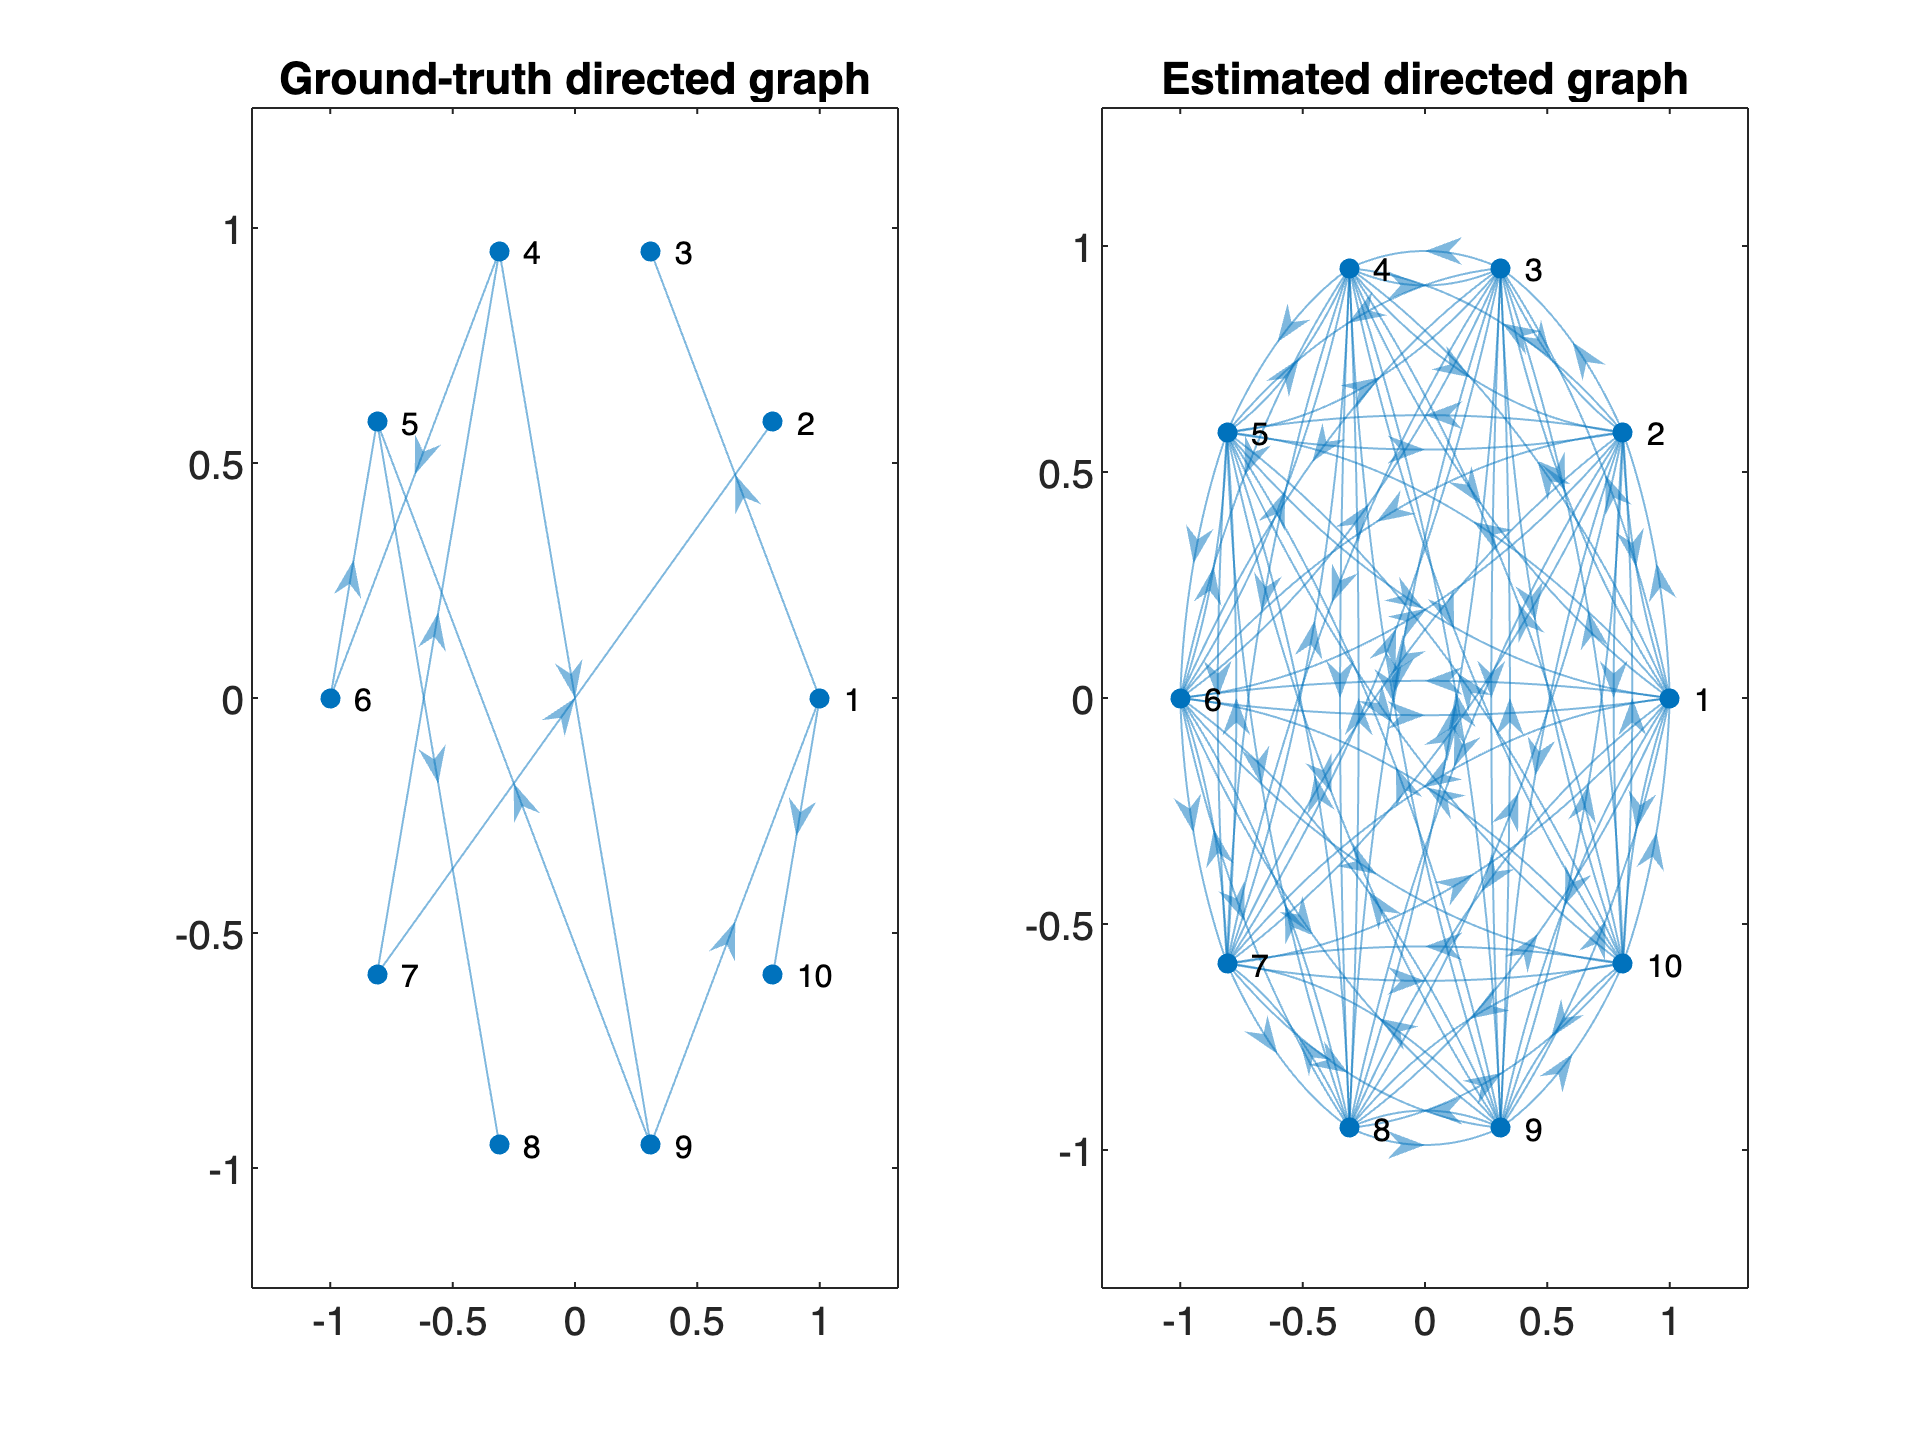

noise_level = 10;
What = C_truth + noise_level * randn(n); % estimation
What(1:n+1:end) = 0;
Ghat = digraph(What);

figure;
subplot(1,2,1)
plot(G, 'XData', G.Nodes.X, 'YData', G.Nodes.Y);
title('Ground-truth directed graph')

subplot(1,2,2)
plot(Ghat, 'XData', G.Nodes.X, 'YData', G.Nodes.Y);
title('Estimated directed graph')

To design a proper ROC analysis, we must first construct a binary outcome that distinguishes true signals from null cases. Let $y_i \in \{0,1\}$ denote the ground-truth label, where $y_i = 1$ corresponds to a true signal (positive) and $y_i = 0$ corresponds to a null (negative). In addition, we require a suitable score function that reflects the strength of evidence for each observation. Let $s_i$ denote the score produced by a method, where larger values indicate stronger evidence for the positive class. For a given threshold $c$, we classify observations according to $\hat{y}_i(c) = \mathbf{1}(s_i \ge c),$ so that observations with scores exceeding the threshold are declared positive. Varying the threshold $c$ produces different trade-offs between correctly detected signals and false alarms.

The rule $y_{ij} = \mathbf{1}\big(C_{\mathrm{truth}}(i,j) \neq 0\big)$ converts the weighted ground-truth network into a binary edge-existence problem, where $y_{ij}=1$ indicates that a true edge is present and $y_{ij}=0$ indicates that no edge exists.

idx = ~eye(n); %index for nondiagonal entries
y = C_truth(idx) ~= 0; 

The quantity $s_{ij} = |\widehat{W}(i,j)|$ defines a score that measures the strength of evidence for an edge based on the estimated weighted network. Larger values of $s_{ij}$ indicate stronger evidence that an edge is present.

s = abs(What(idx));

Then, ROC analysis evaluates how well the estimated scores  rank true edges above non-edges. In particular, it quantifies the ability of the method to assign higher scores to pairs $(i,j)$ for which $C_{\mathrm{truth}}(i,j) \neq 0$ than to those for which $C_{\mathrm{truth}}(i,j) = 0$. This corresponds to assessing the edge-detection performance of the method, independent of any specific threshold.

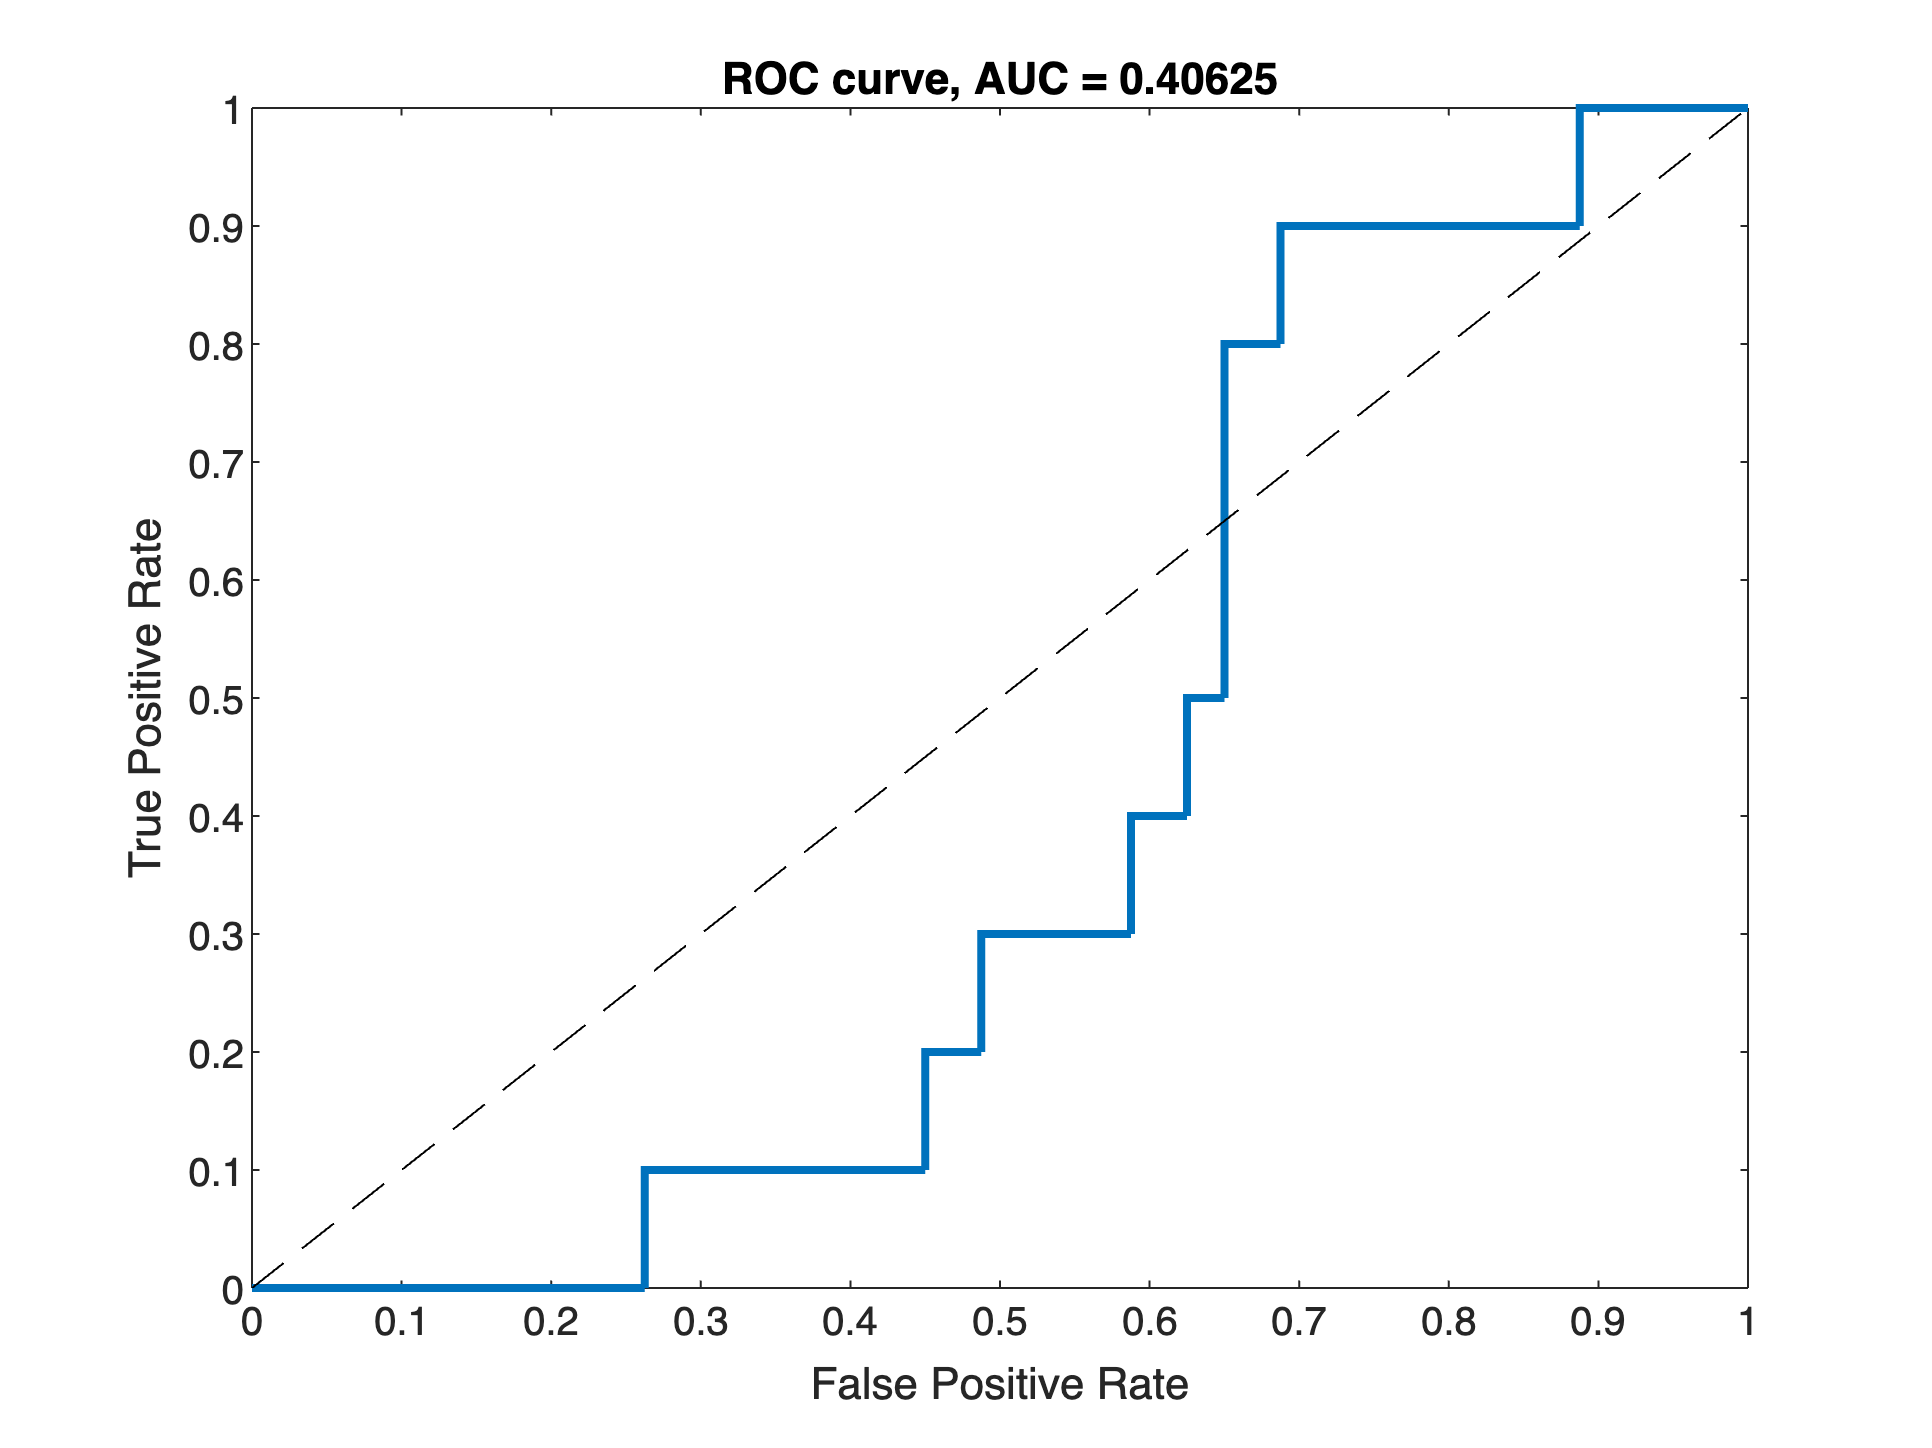

[FPR, TPR, T, AUC] = perfcurve(y, s, 1);

figure;
stairs(FPR, TPR, 'LineWidth', 2); hold on;
plot([0 1], [0 1], '--k');
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC curve, AUC = ', num2str(AUC)]);

% axis square; grid on;

### Disucssion

Although ROC analysis is defined in terms of binary decisions, it naturally extends to continuous decision rules through the score $s_i$. A continuous-valued scoring function induces a family of binary classifiers indexed by the threshold $c$. Varying $c$ over the range of possible score values generates the ROC curve, which traces the trade-off between the true positive rate and the false positive rate across all operating points. In this sense, ROC analysis does *not require a single fixed binary decision rule*, but rather evaluates the entire continuum of decision rules derived from the underlying score. Consequently, ROC provides a threshold-independent assessment of how well the continuous score separates positive and negative classes.